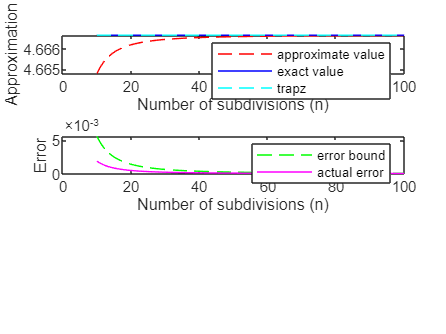

clc; clear; close all;

figure;
hold on;

left = 10;
right = 100;

a = 0;
b = 3;

k = 0.25;

x = left:right;
y = nan(1, right - left + 1);

actual_integral = (2/3)*(b+1)^(3/2) - (2/3)*(a+1)^(3/2);
actual_integral_vec = ones(1, right - left + 1) .* actual_integral;

error_bound = nan(1, right - left + 1);
actual_error = nan(1, right - left + 1);

for n = left:right
    deltaX = (b - a) / n;
    
    xi = a + linspace((b-a)/n/2,b-((b-a)/n/2), n);
    
    s1 = sqrt(xi - (b-a)/n/2 + 1);
    s2 = sqrt(xi + (b-a)/n/2 + 1);
    
    sum_trap = sum((s1 + s2) / 2 * deltaX);
    y(n - (left - 1)) = sum_trap;
    
    error_bound(n - (left - 1)) = ((b - a) ^ 3) * k / (12 * n ^ 2);
    actual_error(n - (left - 1)) = abs(actual_integral - sum_trap);
end

m = linspace(0,3,1000);
p = ones(1, right - left + 1) .* (trapz(m,sqrt(m+1)));

subplot(3,1,1);
plot(x, y, "r--", x, actual_integral_vec, "b", x, p, "c--");
xlabel("Number of subdivisions (n)");
ylabel("Approximation");
legend("approximate value", "exact value", "trapz", "Location", "southeast");

subplot(3,1,2);
plot(x, error_bound,"g--", x, actual_error, "m");
xlabel("Number of subdivisions (n)");
ylabel("Error");
legend("error bound", "actual error");